# Train Biped Robot to Walk Using DDPG Agent

This example shows how to train a biped robot, modeled in Simscape™ Multibody™, to walk using a deep deterministic policy gradient (DDPG) reinforcement learning agent. For more information on DDPG agents, see [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_66c8fe60-f58e-4bdb-904a-21d442f0a879).

## Biped Robot Model

The reinforcement learning environment for this example is a biped robot. The training goal is to make the robot walk in a straight line without aggressive or unrealistic motions using minimal control effort.

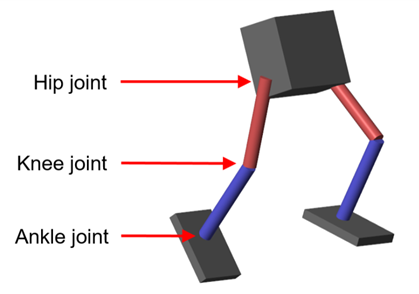

Add necessary paths, and load parameters of the model to the base MATLAB® workspace.

addpath(genpath('Scripts'),genpath('Lib'))
robotParametersRL;

Open the model.

mdl = 'rlWalkingBipedRobot';
open_system(mdl)

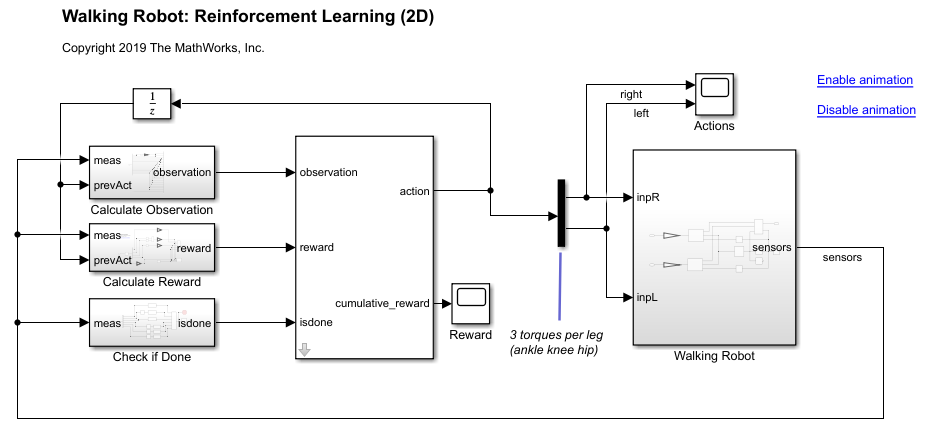

The robot is modeled using Simscape Multibody and the [Simscape Multibody Contact Forces Library](https://www.mathworks.com/matlabcentral/fileexchange/47417-simscape-multibody-contact-forces-library).

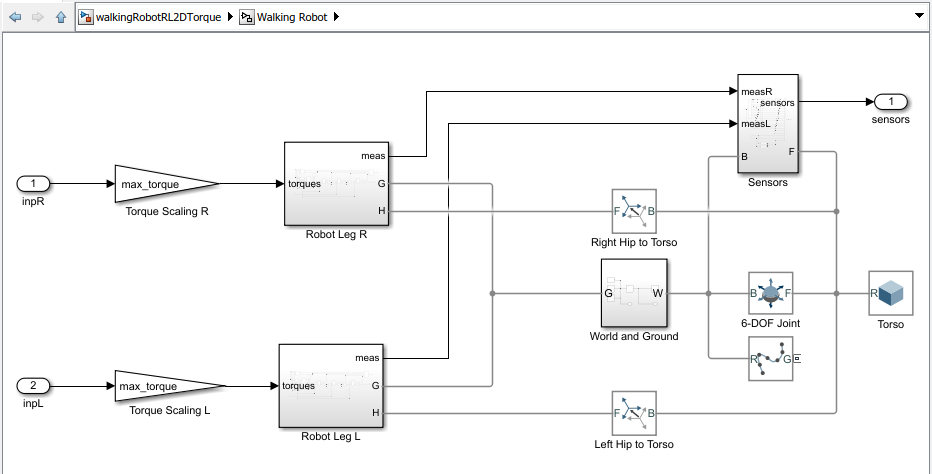

For this model:

- The neutral `0` radian position is with both legs straight and the ankles flat.

- The foot contact is modeled using the [Simscape Multibody Contact Forces Library](https://www.mathworks.com/matlabcentral/fileexchange/47417-simscape-multibody-contact-forces-library).

- The agent can control 3 individual joints, the ankle, knee, and hip, on both legs of the robot by applying torque signals from `-3` to `3` Nm. The actual computed action signals are normalized to be from `-1` to 1`.`

- The environment provides 29 observations to the agent. The observations are: Y (lateral) and Z (vertical) translations of the torso center of mass; X (forward), Y (lateral), and Z (vertical) translation velocities; yaw, pitch, and roll angles of the torso; yaw, pitch, and roll angular velocities; angular position and velocity of 3 joints (ankle, knee, hip) on both legs; and previous actions from the agent. The translation in the Z direction is normalized to a similar range as the other observations.

- The episode terminates if the robot torso center of mass is less than 0.1 m in Z direction (fallen) or more than 1 m in Y direction (lateral motion). The episode also terminates if the absolute value of either the roll, pitch, or yaw is greater than 0.7854.

- The reward function $r_t$, provided at every timestep, is inspired by [1]. This reward function encourages the agent to move forward by giving a positive reward for forward velocity. It also encourages the agent to avoid episode termination by giving a constant reward ($25\frac{\mathrm{Ts}}{\mathrm{Tf}}$) every time step. On the other hand, it penalizes substantial changes in lateral and horizontal translations, along with the control effort.


$${\mathit{\mathbf{r}}}_{\mathit{\mathbf{t}}} =v_x -{3y}^2 -50{\hat{z} }^2 +25\frac{\mathrm{Ts}}{\mathrm{Tf}}-0\ldotp 02\sum_i {u_{t-1}^i }^2$$


where:

- $v_x$ is the translation velocity in X direction (forward toward goal) of the robot.

- $y$ is the lateral translation displacement of the robot from the target straight line trajectory.

- $\hat{z}$ is the normalized horizontal translation displacement of the robot center of mass.

- $u_{t-1}^i$ is the torque from joint $i$ from the previous time step.

- $\mathrm{Ts}$ is the sample time of the environment.

- $\mathrm{Tf}$ is the final simulation time of the environment.

## Create Environment Interface

Create the observation specification.

numObs = 29+22;
obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = 'observations';

Create the action specification.

numAct = 12;
actInfo = rlNumericSpec([numAct 1],'LowerLimit',-1,'UpperLimit', 1);
actInfo.Name = 'foot_torque';

Create the environment interface for the walking robot model.

blk = [mdl,'/RL Agent'];
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);
env.ResetFcn = @(in) walkerResetFcn(in,upper_leg_length/100,lower_leg_length/100,h/100);

## Create DDPG agent

A DDPG agent approximates the long-term reward given observations and actions using a critic value function representation. A DDPG agent decides which action to take given observations using an actor representation. The actor and critic networks for this example are inspired by [2].

For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004). For an example that creates neural networks for DDPG agents, see [Train DDPG Agent to Control Double Integrator System](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

Create the actor and critic networks using the `createRobotNetworks` helper function.

[criticNetwork,actorNetwork] = createNetworks(numObs,numAct);

View the critic network configuration.

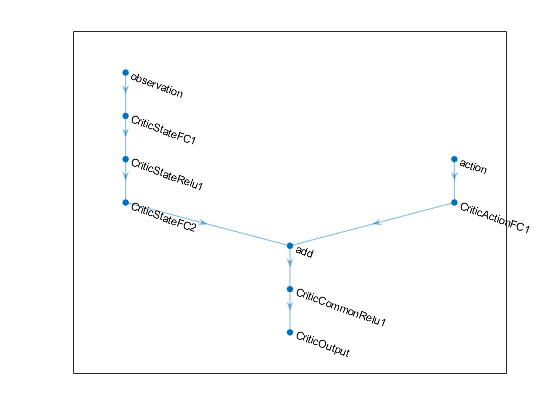

figure
plot(criticNetwork)

Specify options for the critic and actor representations using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',1e-3, ... 
                                        'GradientThreshold',1,'L2RegularizationFactor',1e-5);
actorOptions = rlRepresentationOptions('Optimizer','adam','LearnRate',1e-4, ...
                                       'GradientThreshold',1,'L2RegularizationFactor',1e-5);

Create the critic and actor representations using the specified deep neural networks and options. You must also specify the action and observation information for each representation, which you already obtained from the environment interface. For more information, see [`rlRepresentation`](docid:rl_ref#mw_453a7f45-3761-4387-9e1d-4c90ed8b5b57).

critic = rlRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'observation'},'Action',{'action'},criticOptions);
actor  = rlRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'observation'},'Action',{'ActorTanh1'},actorOptions);

To create the DDPG agent, first specify the DDPG agent options using [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

agentOptions = rlDDPGAgentOptions;
agentOptions.SampleTime = Ts;
agentOptions.DiscountFactor = 0.99;
agentOptions.MiniBatchSize = 128;
agentOptions.ExperienceBufferLength = 1e6;
agentOptions.TargetSmoothFactor = 1e-3;
agentOptions.NoiseOptions.MeanAttractionConstant = 1;
agentOptions.NoiseOptions.Variance = 0.1;

Then, create the DDPG agent using the specified actor representation, critic representation, and agent options. For more information, see [`rlDDPGAgent`](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor,critic,agentOptions);

## Training Options

To train the agent, first specify the training options. For this example, use the following options:

- Run each training episode for at most 20000 episodes, with each episode lasting at most 400 time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option).

- Stop training when the agent receives an average cumulative reward greater than 100 over 250 consecutive episodes. At this point, the agent can quickly balance the pendulum in the upright position using minimal control effort.

- Save a copy of the agent for each episode where the cumulative reward is greater than 150.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxEpisodes = 20000;
maxSteps = Tf/Ts;
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxEpisodes,...
    'MaxStepsPerEpisode',maxSteps,...
    'ScoreAveragingWindowLength',250,...
    'Verbose',false,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',100,...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue',150);

To train the agent in parallel, specify the following training options. 

- Set the `UseParallel` option to t`rue`.

- Train the agent in parallel asynchronously.

- After every 32 steps, each worker sends experiences to the host. 

- DDPG agents require workers to send `'Experiences'` to the host.

trainOpts.UseParallel = true;
trainOpts.ParallelizationOptions.Mode = 'async';
trainOpts.ParallelizationOptions.StepsUntilDataIsSent = 32;
trainOpts.ParallelizationOptions.DataToSendFromWorkers = 'Experiences';

## Train Agent

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This process is computationally intensive and takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`. Due to randomness of the parallel training, you can expect different training results from the plot below. The example is trained with six workers.

doTraining = 1;

if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load('rlWalkingBipedRobotDDPG.mat','agent')
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


错误使用 parallel.Future/fetchOutputs (line 346)
One or more futures resulted in an error.

出错 rl.train.ParTrainManager/asyncDistributeTask (line 108)
                    simInfoWorkerCell = fetchOutputs(F,'UniformOutput',false);

出错 

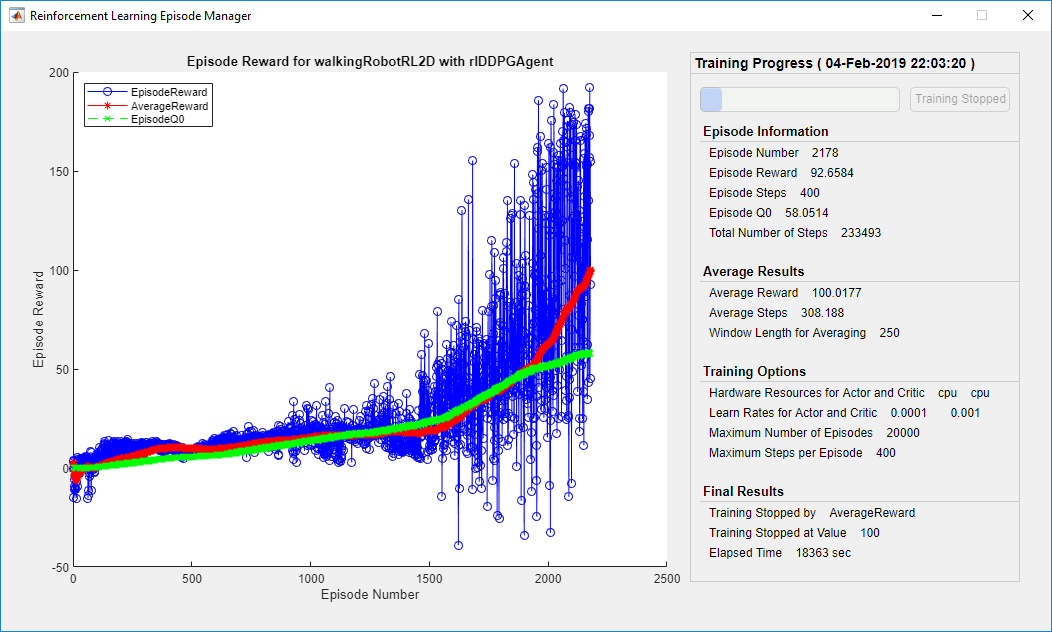

## Simulate DDPG Agent

Fix the random generator seed for reproducibility.

rng(0)

To validate the performance of the trained agent, simulate it within the cart-pole environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions('MaxSteps',maxSteps);
experience = sim(env,agent,simOptions);

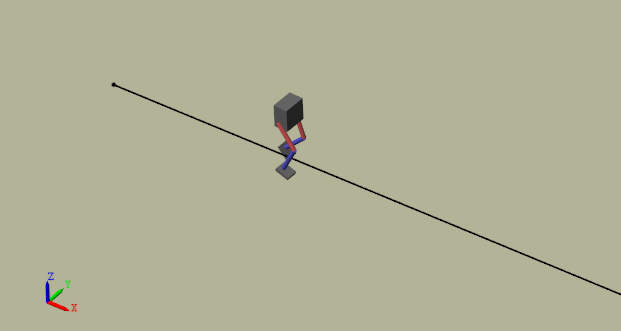

## References

[1] N. Heess et al, "[Emergence of Locomotion Behaviours in Rich Environments](https://arxiv.org/pdf/1707.02286.pdf)," Technical Report, *ArXiv*, 2017.

[2] T.P. Lillicrap et al, "[Continuous Control with Deep Reinforcement Learning](https://arxiv.org/pdf/1509.02971.pdf)," *International Conference on Learning Representations*, 2016.

*Copyright 2018-2019 The MathWorks, Inc.*

*MATLAB and Simulink are registered trademarks of The MathWorks, Inc. Please see* [*www.mathworks.com/trademarks*](https://www.mathworks.com/trademarks) *for a list of other trademarks owned by The MathWorks, Inc. Other product or brand names are trademarks or registered trademarks of their respective owners.*